# The Power Spectrum of White Noise using the Discrete Fourier Transform (DFT) 

Let us now move to a different statistics: the Power spectrum, which as we have seen, represents the Fourier Transform of the autocorrelation function.

We start with the simplest possible example; **white noise**.

***Author: Annalisa Molini***

***Last updated: Oct 12,2022***

***CREDITS: This script is based on the MatWorks tutorial ***[***https://www.mathworks.com/help/signal/ug/power-spectral-density-estimates-using-fft.html***](https://www.mathworks.com/help/signal/ug/power-spectral-density-estimates-using-fft.html) 

## Signal Sampling and Duration

Let us first define the sampling and duration of our synthetic signal:

Fs = 1000;             % Sampling frequency [in Hz]  
Nyq=Fs/2;             % Nyquist frequency [in Hz]  
T = 1/Fs;             % Sampling period [in seconds]   
L = 15000;             % Length of signal [Number of samples]
t = (0:L-1)*T;        % Time vector [in s]

The next step is to generate the synthetic signal using the time vector t. We start simple, just generating a white noise signal of pre-assigned variance s2n:

% Variance
s2n=8;

% Generate White Noise signal
X = sqrt(s2n)*randn(size(t));

% Check variance of the sample
varnoise=var(X)

varnoise = 7.9108

Let us now plot the noisy signal in the time domain and compare it with the 'periodic' original signal:

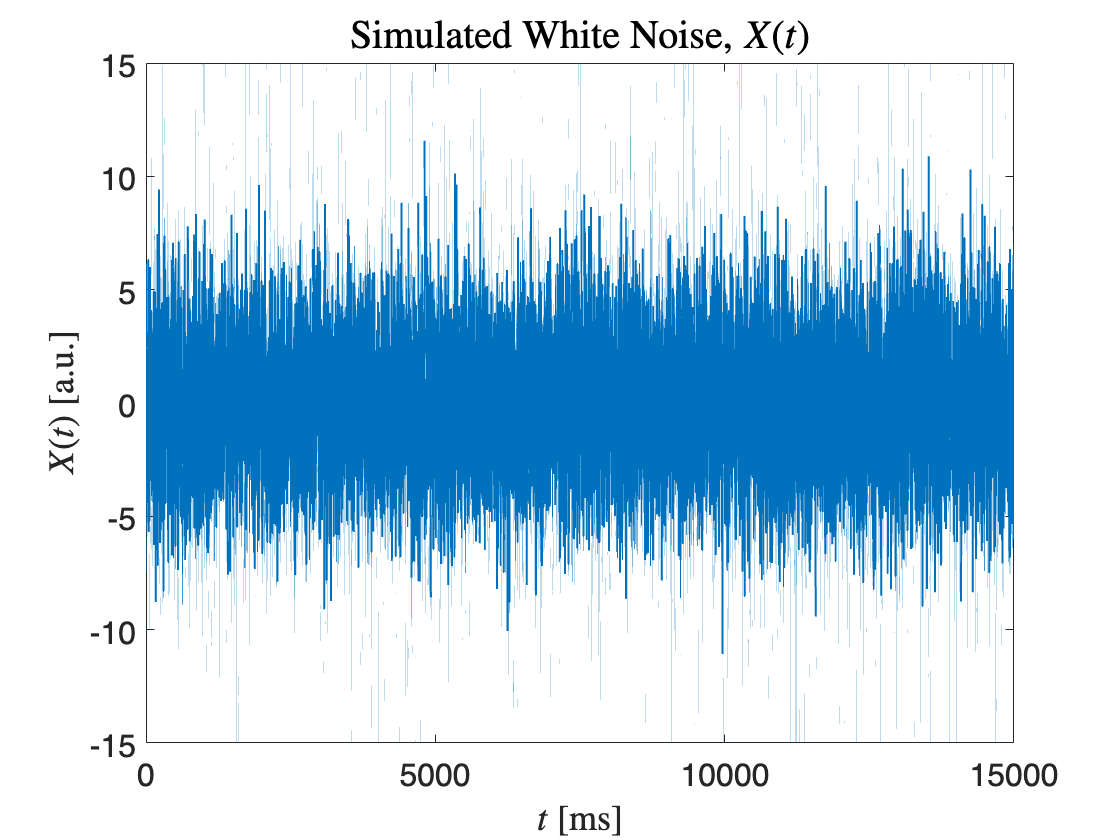

figure;
h1=plot(1000*t,X);
set(h1,'linewidth', 1);
set(gca,'FontSize',16);

% Axex labels
xlabel("$t$ [ms]","FontSize",18,'Interpreter','latex')
ylabel("$X(t)$ [a.u.]","FontSize",18,'Interpreter','latex');
title("Simulated White Noise, $X(t)$","FontSize",20,'Interpreter','latex')

hold off;

The next step is to compute the Fourier transform of the signal:

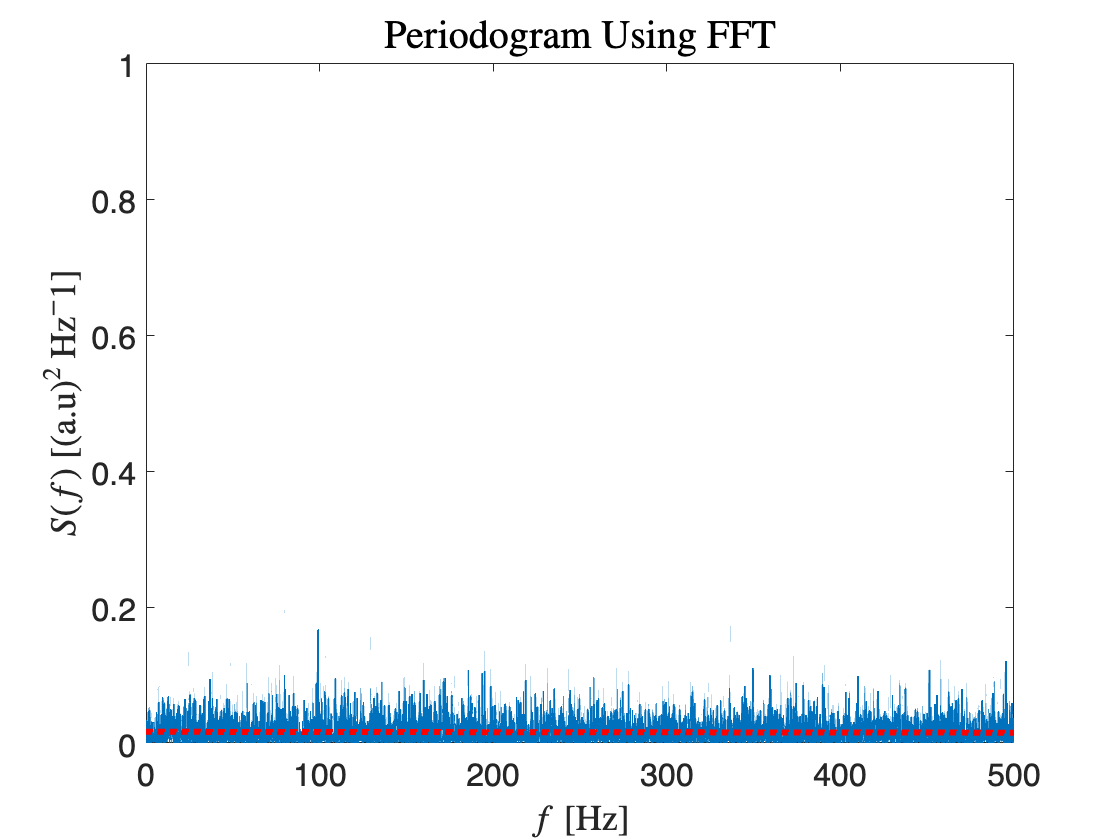

Y = fft(X);
Y = Y(1:L/2+1);
S = (1/(Fs*L)) * abs(Y).^2; % Dividing by L and Fs we obtain a Power (Energy per unit of time) per unit of frequency
S(2:end-1) = 2*S(2:end-1);
f = Fs*(0:(L/2))/L;

figure;
h2=plot(f,S);
%h2=plot(f,S/varnoise);
set(h2,'linewidth', 1);
set(gca,'FontSize',16);

title("Periodogram Using FFT","FontSize",20,'Interpreter','latex');
xlabel("$f$ [Hz]","FontSize",18,'Interpreter','latex');
ylabel("$S(f)$ [(a.u)$^2$ Hz$^-1$]","FontSize",18,'Interpreter','latex');

ylim([0,1]);

% fit lineare
p = polyfit(f,S,1);
y = polyval(p,f);

hold on;
h4=plot(f,y);
set(h4,'Linewidth', 3,'Color','r','Linestyle',':');
hold off;

% Verify Normalization
% Area of the spectrum
ASpec=y(1)*Nyq

ASpec = 8.2237

And just to reconnect to the discussion on 1/f noise during last class, let us plot the spectrum in loglog (and its fitting):

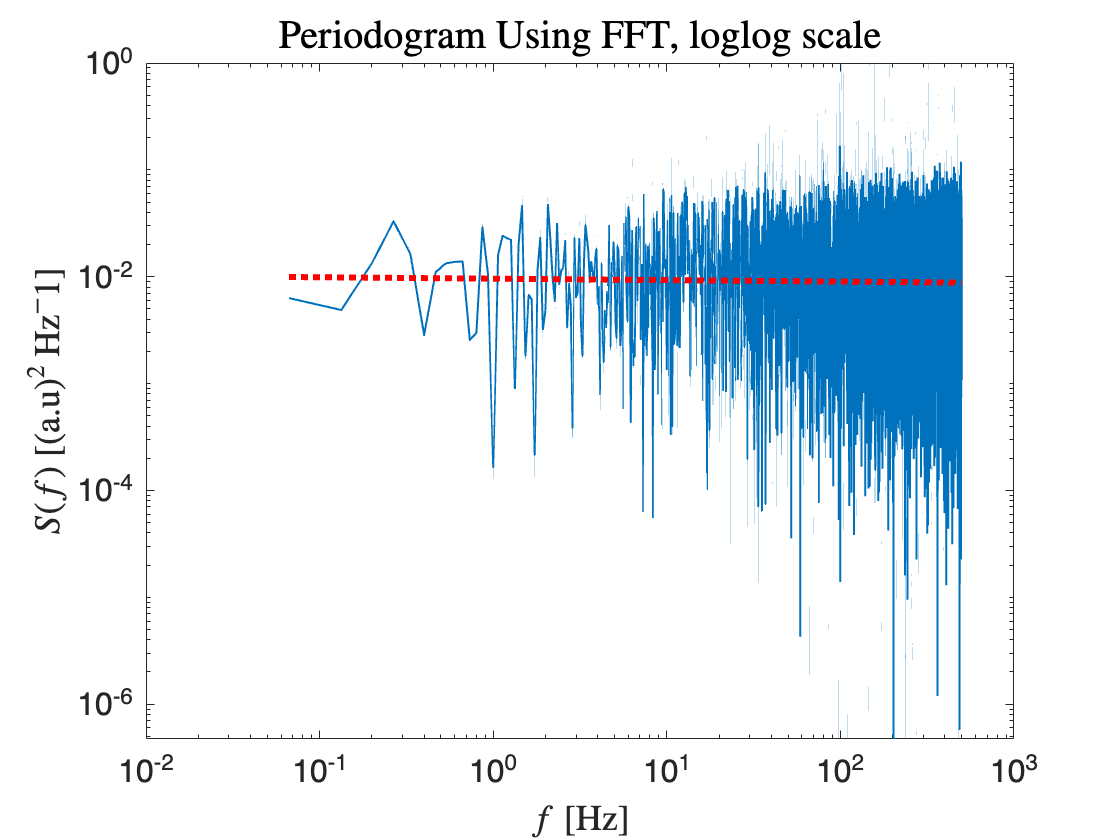

% fitting log (this is a different fitting, since we are now using a power
% law in the loglog space. However, for white noise (flat spectrum) the
% result should be smilar
%f(1)=10^(-20);
p2 = polyfit(log10(f(2:end)),log10(S(2:end)),1);
y2=10^(p2(2))*f.^(p2(1)); 

figure;
h3=loglog(f,S);
set(h3,'linewidth', 1);
set(gca,'FontSize',16);

hold on;
h4=loglog(f,y2);
set(h4,'Linewidth', 3,'Color','r','Linestyle',':');

% h5=area(f,y);
% h5.FaceColor = 'cyan';
% h5.FaceAlpha = 0.05;
hold off;
set(h4,'Linewidth', 3,'Color','r','Linestyle',':');

title("Periodogram Using FFT, loglog scale","FontSize",20,'Interpreter','latex')
xlabel("$f$ [Hz]","FontSize",18,'Interpreter','latex')
ylabel("$S(f)$ [(a.u)$^2$ Hz$^-1$]","FontSize",18,'Interpreter','latex')